# LSB Coding

[y, Fs] = audioread("audio.wav");
player = audioplayer(y, Fs);
play(player);

stop(player);

lena = imread('lena_std.tif');
lena_gray = rgb2gray(lena);
img_size = 512;
crop_range = img_size*img_size*8;
scaled = 10000;

% encryted the image by key
key = 3;
lena_gray_en = encryption2D(lena_gray, key);

% convert image from decimal to binary
lena_gray_ext = de2bi(lena_gray_en.');
% convert audio from decimal to binary
y_tmp = floor(y(1:crop_range)*scaled);
y_ext = de2bi_ext(y_tmp);

% Encode bits to LSB in audio
[l, bit] = size(y_ext);
t = 1;
for i = 1:img_size*img_size
    for j = 1:8
        y_ext(t, 1) = lena_gray_ext(i, j);
        t = t + 1;
    end 
end
y_r = bi2de_ext(y_ext)/scaled;

player = audioplayer(y_r, Fs);
play(player);

stop(player);

% Decode image bits from LSB in audio
scaled = 10000;
y_test = int32(y_r*scaled);
y_test_t = de2bi_ext(y_test);

N = 512;
lena_img_bin = zeros(N*N, 8);
t = 1;
for i = 1:N*N
    for j = 1:8
        lena_img_bin(i, j) = y_test_t(t, 1);
        t = t + 1;
    end
end
lena_img_re = bi2de(lena_img_bin);
lena_img_re = reshape(lena_img_re, N, N).';

% decrypted using key
key = 3;
lena_img_de = decryption2D(lena_img_re, key);

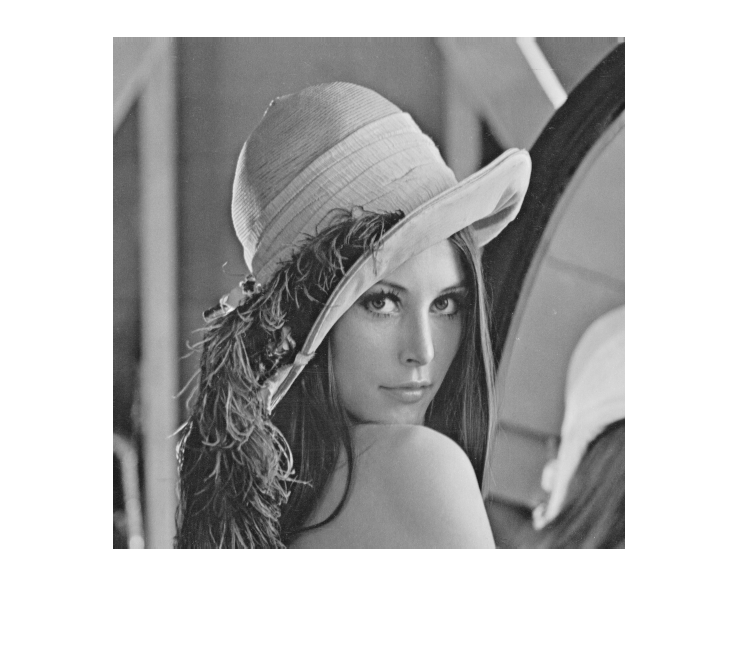

figure;
imshow(uint8(lena_img_de));

# Some qualitative results

Image

gen = uint8(lena_img_de);
ref = lena_gray;

[peaksnr, snr] = psnr(gen, ref)

peaksnr = Inf

snr = Inf

mse = immse(gen, ref)

mse = 0

[ssimval, ssimmap] = ssim(gen, ref)

ssimval = 1

ssimmap =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

Sound

[peaksnr, snr] = psnr(y_r, y(1:crop_range))

peaksnr = 80.7981

snr = 61.2462

mse = mean((y_r - y(1:crop_range)).^2)

mse = 8.3212e-09

clear all;